% %Koble raspberry pi til matlab 192.168.43.6
% clear mypi;
% clear;
% mypi=raspi("IP-adresse","Rpi-Brukernavn","Rpi-Passord");

% %Sample fra ADC-ene og lagre i en fil som overføres til denne mappen, og deretter slette filen fra pi-en
% system(mypi,'lab1/./adc_sampler 31250 /home/Kollis/lab1/datafiler/SAMPLE.bin','sudo');
% getFile(mypi,'/home/Kollis/lab1/datafiler/SAMPLE.bin','C:\Users\skaug\OneDrive\Skole\2024-06-VÅR\TTT4280 - Sensorer og instrumentering\Lab\Lab1 - Systemoppsett\Data');
% deleteFile(mypi,'/home/Kollis/lab1/datafiler/SAMPLE.bin');

channels=5;
nBits=12;
VDD=3.3;

fid=fopen("1kHzSine.bin","rb");

nomPeriod=fread(fid,1,"double");
data=fread(fid,"uint16");

nSamples=numel(data)/channels; %Antall sampler per ADC
dataMatrix = reshape(data,channels,nSamples); %Matrise med verdiene til ADC-ene i hver rad
fclose(fid);

nomPeriod = nomPeriod * 1e-6;
n=1:nSamples;
t=n*nomPeriod;
h=transpose(hann(nSamples)); %Hanning Vindu med samme lengde som antall sampler
flat=transpose(flattopwin(nSamples,'periodic'));

%Omformer matrisen til array av hver ADC, med riktig spenningsverdier
ADC1=dataMatrix(1,:)*VDD/2.^(nBits); 
ADC2=dataMatrix(2,:)*VDD/2.^(nBits);
ADC3=dataMatrix(3,:)*VDD/2.^(nBits);
ADC4=dataMatrix(4,:)*VDD/2.^(nBits);
ADC5=dataMatrix(5,:)*VDD/2.^(nBits);

ADC1=ADC1-mean(ADC1); 
ADC2=ADC2-mean(ADC2);
ADC3=ADC3-mean(ADC3);
ADC4=ADC4-mean(ADC4);
ADC5=ADC5-mean(ADC5);

%Tidsserie
figure;
sgtitle("Samplet ADC-er",'fontsize',30,'FontWeight','bold');

subplot(3,2,[1 2]);
plot(t,ADC1,'color',[0.4660 0.6740 0.1880],'LineWidth',3);
ylabel("[V]"); ylim([-1.5, 1.5]);
xlabel("t [s]"); xlim([t(10000) t(10200)]);
title("ADC_1(t)",'color',[0.4660 0.6740 0.1880],'fontsize',20)
legend("SNR="+snr(ADC1),'fontsize',20)
grid;
ax = gca

ax =   Axes (ADC_1(t)) with properties:

             XLim: [0.3200 0.3264]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.7093 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


ax.GridLineWidth = 1;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes (ADC_1(t)) with properties:

             XLim: [0.3200 0.3264]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.1300 0.7093 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';
set(ax.YLabel,'rotation',0);

subplot(3,2,3);
plot(t,ADC2,'color',[0.8500 0.3250 0.0980],'LineWidth',3);
ylabel("[V]"); ylim([-1.5, 1.5]);
xlabel("t [s]"); xlim([t(10000) t(10200)]);
title("ADC_2(t)",'color',[0.8500 0.3250 0.0980],'fontsize',20)
legend("SNR="+snr(ADC2),'fontsize',20)
grid;
ax = gca

ax =   Axes (ADC_2(t)) with properties:

             XLim: [0.3200 0.3264]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


ax.GridLineWidth = 1;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes (ADC_2(t)) with properties:

             XLim: [0.3200 0.3264]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.1300 0.4096 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';
set(ax.YLabel,'rotation',0);

subplot(3,2,4);
plot(t,ADC3,'color',"b",'LineWidth',3);
ylabel("[V]"); ylim([-1.5, 1.5]);
xlabel("t [s]"); xlim([t(10000) t(10200)]);
title("ADC_3(t)",'color',"b",'fontsize',20)
legend("SNR="+snr(ADC3),'fontsize',20)
grid;
ax = gca

ax =   Axes (ADC_3(t)) with properties:

             XLim: [0.3200 0.3264]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.4096 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


ax.GridLineWidth = 1;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes (ADC_3(t)) with properties:

             XLim: [0.3200 0.3264]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.5703 0.4096 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';
set(ax.YLabel,'rotation',0);

subplot(3,2,5);
plot(t,ADC4,'color',[0.6350 0.0780 0.1840],'LineWidth',3);
ylabel("[V]"); ylim([-1.5, 1.5]);
xlabel("t [s]"); xlim([t(10000) t(10200)]);
title("ADC_4(t)",'color',[0.6350 0.0780 0.1840],'fontsize',20)
legend("SNR="+snr(ADC4),'fontsize',20)
grid;
ax = gca

ax =   Axes (ADC_4(t)) with properties:

             XLim: [0.3200 0.3264]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


ax.GridLineWidth = 1;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes (ADC_4(t)) with properties:

             XLim: [0.3200 0.3264]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.1300 0.1100 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';
set(ax.YLabel,'rotation',0);

subplot(3,2,6);
plot(t,ADC5,'color',"m",'LineWidth',3);
ylabel("[V]"); ylim([-1.5, 1.5]);
xlabel("t [s]"); xlim([t(10000) t(10200)]);
title("ADC_5(t)",'color',"m",'fontsize',20)
legend("SNR="+snr(ADC5),'fontsize',20)
grid;
ax = gca

ax =   Axes (ADC_5(t)) with properties:

             XLim: [0.3200 0.3264]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


ax.GridLineWidth = 1;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes (ADC_5(t)) with properties:

             XLim: [0.3200 0.3264]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.5703 0.1100 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


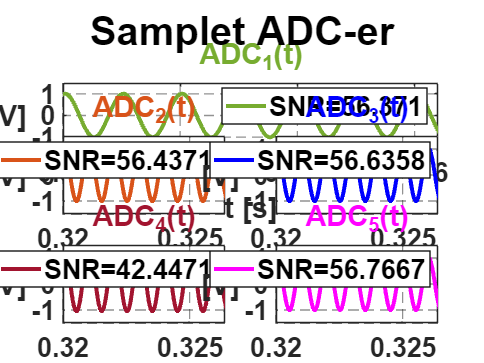

ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';
set(ax.YLabel,'rotation',0);

N_fft=2.^(15);
A1=abs(fftshift(fft(flat.*ADC1,N_fft)));
A2=abs(fftshift(fft(flat.*ADC2,N_fft)));
A3=abs(fftshift(fft(h.*ADC3,N_fft)));
A4=abs(fftshift(fft(h.*ADC4,N_fft)));
A5=abs(fftshift(fft(h.*ADC5,N_fft)));
f_fft=1/(N_fft*nomPeriod)*(-N_fft/2:N_fft/2-1);

S1=20*log10(A1./max(A1));
S2=20*log10(A2./max(A2));
S3=20*log10(A3./max(A3));
S4=20*log10(A4./max(A4));
S5=20*log10(A5./max(A5));

%Frekvensspekter / Effekttetthet
figure;

%sgtitle("Relativ effekttetthet S_{ADC}, N_{FFT}="+N_fft);
subplot(3,2,[1 2]);
plot(f_fft,S1,'color',[0.4660 0.6740 0.1880]);
ylabel("[dB]"); ylim([-120 0]);
xlabel("f [Hz]"); xlim([-1.5 1.5]*10.^4);
title("S_{ADC_1}(f)",'color',[0.4660 0.6740 0.1880],'fontsize',20)
legend("SNR="+snr(ADC1),'fontsize',20)
axis tight;
grid;
ax = gca

ax =   Axes (S_{ADC_1}(f)) with properties:

             XLim: [-15625 1.5624e+04]
             YLim: [-144.7676 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.7093 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


ax.GridLineWidth = 1;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes (S_{ADC_1}(f)) with properties:

             XLim: [-15625 1.5624e+04]
             YLim: [-144.7676 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.1300 0.7093 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';
set(ax.YLabel,'rotation',0);

subplot(3,2,3);
plot(f_fft,S2,'color',[0.8500 0.3250 0.0980]);
ylabel("[dB]"); ylim([-120 0]);
xlabel("f [Hz]"); xlim([-1.5 1.5]*10.^4);
title("S_{ADC_2}(f)",'color',[0.8500 0.3250 0.0980],'fontsize',20)
legend("SNR="+snr(ADC2,1./nomPeriod,8),'fontsize',20)
axis tight;
grid;
ax = gca

ax =   Axes (S_{ADC_2}(f)) with properties:

             XLim: [-15625 1.5624e+04]
             YLim: [-141.1828 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


ax.GridLineWidth = 1;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes (S_{ADC_2}(f)) with properties:

             XLim: [-15625 1.5624e+04]
             YLim: [-141.1828 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.1300 0.4096 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';
set(ax.YLabel,'rotation',0);

subplot(3,2,4);
axis tight;
plot(f_fft,S3,'color',"b");
ylabel("[dB]"); ylim([-120 0]);
xlabel("f [Hz]"); xlim([-1.5 1.5]*10.^4);
title("S_{ADC_3}(f)",'color',"b",'fontsize',20)
legend("SNR="+snr(ADC3,1./nomPeriod,8),'fontsize',20)
axis tight;
grid;
ax = gca

ax =   Axes (S_{ADC_3}(f)) with properties:

             XLim: [-15625 1.5624e+04]
             YLim: [-140.1992 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.4096 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


ax.GridLineWidth = 1;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes (S_{ADC_3}(f)) with properties:

             XLim: [-15625 1.5624e+04]
             YLim: [-140.1992 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.5703 0.4096 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';
set(ax.YLabel,'rotation',0);

subplot(3,2,5);
axis tight;
plot(f_fft,S4,'color',[0.6350 0.0780 0.1840]);
ylabel("[dB]"); ylim([-120 0]);
xlabel("f [Hz]"); xlim([-1.5 1.5]*10.^4);
title("S_{ADC_4}(f)",'color',[0.6350 0.0780 0.1840],'fontsize',20)
legend("SNR="+snr(ADC4),'fontsize',20)
axis tight;
grid;
ax = gca

ax =   Axes (S_{ADC_4}(f)) with properties:

             XLim: [-15625 1.5624e+04]
             YLim: [-136.9073 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


ax.GridLineWidth = 1;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes (S_{ADC_4}(f)) with properties:

             XLim: [-15625 1.5624e+04]
             YLim: [-136.9073 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.1300 0.1100 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';
set(ax.YLabel,'rotation',0);

subplot(3,2,6);
axis tight;
plot(f_fft,S5,'color',"m");
ylabel("[dB]"); ylim([-120 0]);
xlabel("f [Hz]"); xlim([-1.5 1.5]*10.^4);
title("S_{ADC_5}(f)",'color',"m",'fontsize',20)
legend("SNR="+snr(ADC5),'fontsize',20)
axis tight;
grid;
ax = gca

ax =   Axes (S_{ADC_5}(f)) with properties:

             XLim: [-15625 1.5624e+04]
             YLim: [-139.6763 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


ax.GridLineWidth = 1;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes (S_{ADC_5}(f)) with properties:

             XLim: [-15625 1.5624e+04]
             YLim: [-139.6763 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.5703 0.1100 0.3347 0.2157]
            Units: 'normalized'

  Show all properties


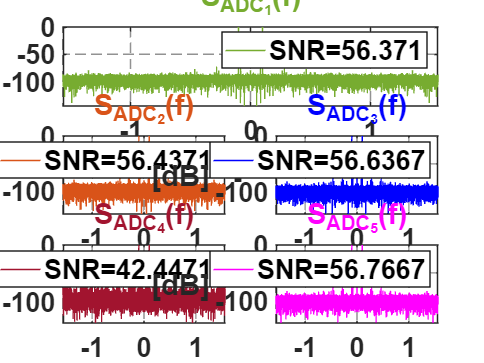

ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';
set(ax.YLabel,'rotation',0);

disp(snr(ADC1));

   56.3710



disp(snr(ADC2));

   56.4371



disp(snr(ADC3));

   56.6358



disp(snr(ADC4));

   42.4471



disp(snr(ADC5));

   56.7667



Ekstra Figurer og Simuleringen


U=abs(fftshift(fft(ADC1,N_fft)));
SU=20*log10(U./max(U));
l=-length(SU)/2:length(SU)/2-1

l =       -16384      -16383      -16382      -16381      -16380      -16379      -16378      -16377      -16376      -16375      -16374      -16373      -16372      -16371      -16370      -16369      -16368      -16367      -16366      -16365      -16364      -16363      -16362      -16361      -16360      -16359      -16358      -16357      -16356      -16355      -16354      -16353      -16352      -16351      -16350      -16349      -16348      -16347      -16346      -16345      -16344      -16343      -16342      -16341      -16340      -16339      -16338      -16337      -16336      -16335





figure;
axis tight;
hold on;
sgtitle("Relativ effekttetthet til ADC_1(t)",'FontWeight','bold','Fontsize',30);
plot(f_fft,S1,'color',[0.4660 0.6740 0.1880],'LineWidth',2);
plot(f_fft,SU,'color',[0.33 0.41 0.47],'LineWidth',1.5);
ylabel("[dB]"); ylim([-140, 0])
xlabel("f [Hz]"); xlim([900 1100]);
legend("Med Flat Top Vindusfunksjon","Med Rektangulær vindusfunksjon",'fontsize',25)
ax = gca

ax =   Axes with properties:

             XLim: [900 1100]
             YLim: [-140 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


grid;
ax.GridLineWidth = 1;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes with properties:

             XLim: [900 1100]
             YLim: [-140 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


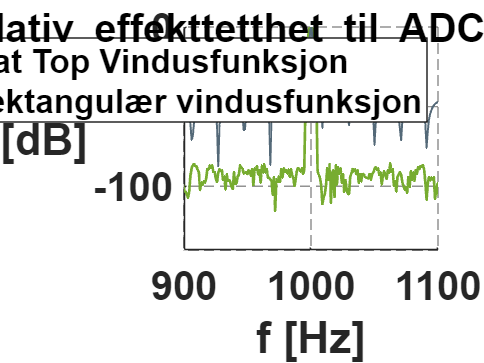

ax.LineWidth = 1;
ax.FontSize=30;
ax.FontWeight='bold';
set(ax.YLabel,'rotation',0);

figure;

U=abs(fftshift(fft(ADC1,N_fft)));
SU=20*log10(U./max(U));

U2=abs(fftshift(fft(h.*ADC1,N_fft)));
SU2=20*log10(U2./max(U2));


subplot(2,2,[1 2]);
plot(f_fft,SU,'color',[1.0 0.75 0.0],'LineWidth',2);
ylabel("[dB]"); ylim([-120, 0])
xlabel("f [Hz]"); xlim([-1500 1500]);
title('Relativ effekttetthet av ADC_1(t) uten vindusfunksjoner','color',[1.0 0.75 0.0],'fontsize',20)
grid;
ax = gca

ax =   Axes (Relativ effekttetthet av ADC_1(t) uten vindusfunksjoner) with properties:

             XLim: [-1500 1500]
             YLim: [-120 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


ax.GridLineWidth = 1;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes (Relativ effekttetthet av ADC_1(t) uten vindusfunksjoner) with properties:

             XLim: [-1500 1500]
             YLim: [-120 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';
set(ax.YLabel,'rotation',0);

subplot(2,2,3);
plot(f_fft,S1,'color',[0.4660 0.6740 0.1880],'LineWidth',1);
ylabel("[dB]"); ylim([-120, 0])
xlabel("f [Hz]"); xlim([-1500 1500]); 
title('Relativ effekttetthet av ADC_1(t) med Flat Top Vindusfunksjon','color',[0.4660 0.6740 0.1880],'fontsize',20)
grid;
ax = gca

ax =   Axes (Relativ effekttetthet av ADC_1(t) med Flat Top Vindusfunksjon) with properties:

             XLim: [-1500 1500]
             YLim: [-120 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


ax.GridLineWidth = 1;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes (Relativ effekttetthet av ADC_1(t) med Flat Top Vindusfunksjon) with properties:

             XLim: [-1500 1500]
             YLim: [-120 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.1300 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';
set(ax.YLabel,'rotation',0);

subplot(2,2,4);
plot(f_fft,SU2,'color',[0.4 0.26 0.13],'LineWidth',1);
ylabel("[dB]"); ylim([-120, 0])
xlabel("f [Hz]"); xlim([-1500 1500]);
title('Relativ effekttetthet av ADC_1(t) med Hanning Vindusfunksjon','color',[0.4 0.26 0.13],'fontsize',20)
grid;
ax = gca

ax =   Axes (Relativ effekttetthet av ADC_1(t) med Hanning Vindusfunksjon) with properties:

             XLim: [-1500 1500]
             YLim: [-120 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


ax.GridLineWidth = 1;
ax.GridAlpha=0.5;
ax.GridLineStyle='--'

ax =   Axes (Relativ effekttetthet av ADC_1(t) med Hanning Vindusfunksjon) with properties:

             XLim: [-1500 1500]
             YLim: [-120 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.5703 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


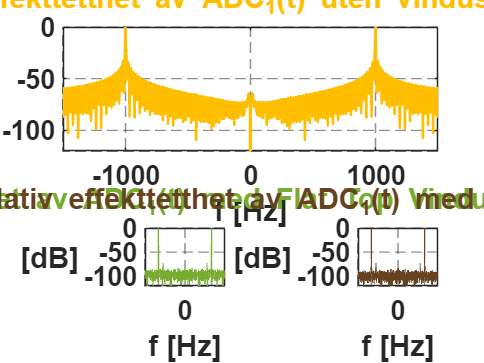

ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';
set(ax.YLabel,'rotation',0);